# **Projet d'AU2**

## ***Léo LEBUHOTEL***

*Déclaration des paramètres d'écriture*

clear all;
clc;
s = settings;
s.matlab.fonts.editor.title.Style.PersonalValue = {'bold'};
s.matlab.fonts.editor.title.Color.PersonalValue = [255 0 0 1]; 
s.matlab.fonts.editor.normal.Size.PersonalValue = 16;
s.matlab.fonts.editor.heading1.Size.PersonalValue = 22;
s.matlab.fonts.editor.normal.Name.PersonalValue = 'Calibri';

## 1 - Modélisation du système

1) Les forces s'appliquant sur le système sont la force électromagnétique créée par l'aimant ainsi que le poids. 

L'application du PFD nous donne l'équation suivante : 


$$m\ldotp \vec{\;a} =\sum \vec{\;F_{\textrm{ext}} }$$


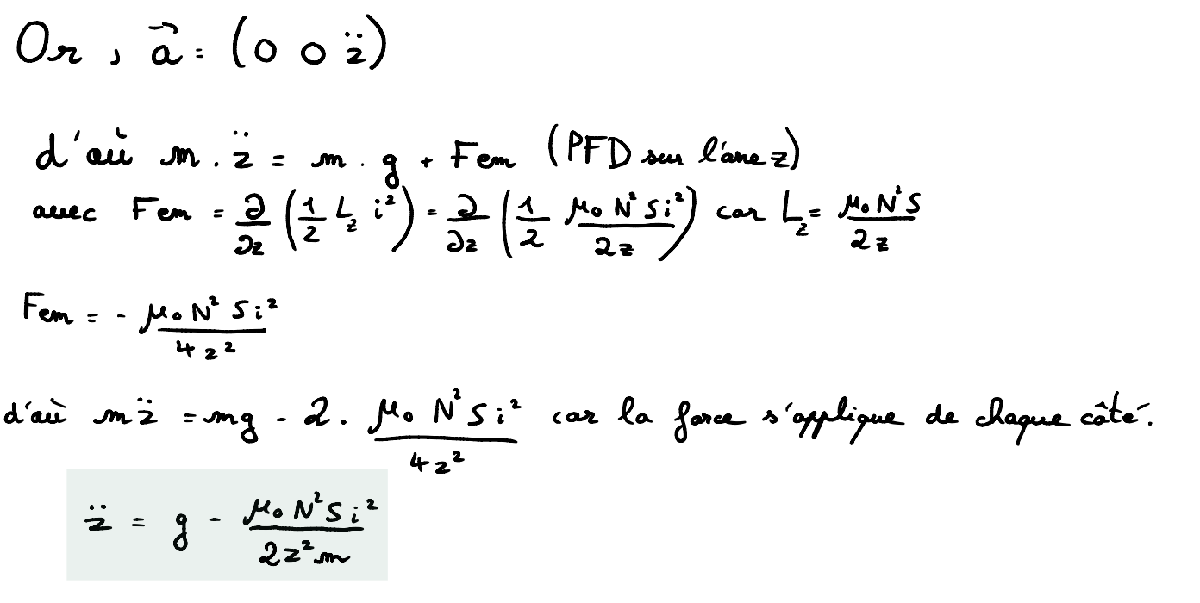

2)

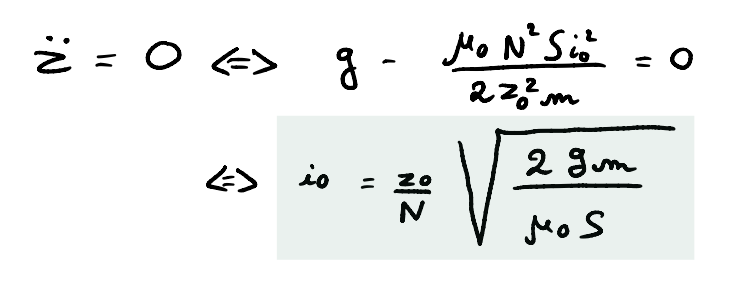

3)

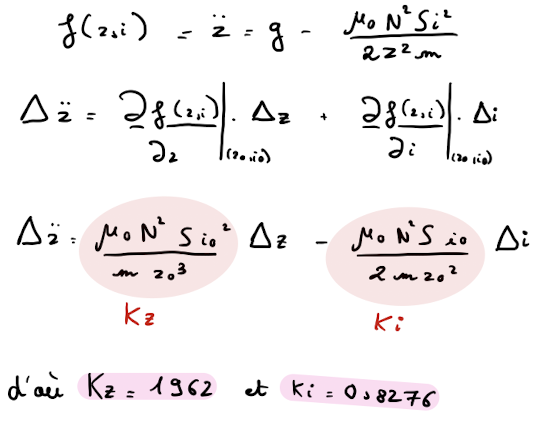

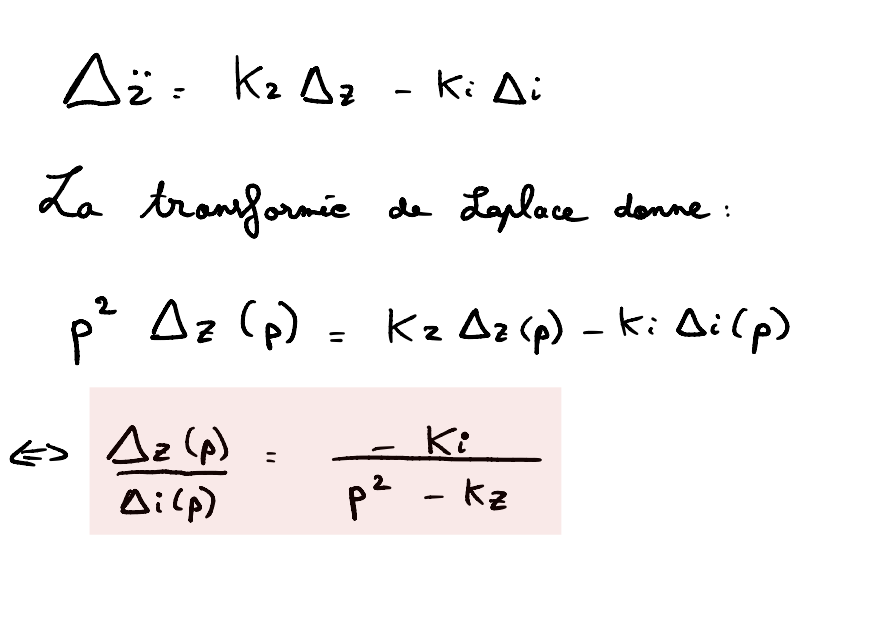

**Déclaration des constantes**

mu = 4*pi *1e-7;
g = 9.81; 
N = 1000;
S = 0.5;
m = 180000;
k1 = 10;
k2 = 145;

**Position d'équilibre n°1 : ***z0 = 10mm*

z0 = 10e-3;
i0 = z0/N * sqrt ((m*g*2)/(mu*S))

i0 = 23.7080

Kz = (mu*N^2*S*i0^2)/(m*z0^3)

Kz = 1962

Ki = (mu*N^2*S*i0)/(m*z0^2)

Ki = 0.8276

**Fonction de transfert continue du processus**

num = -k1*k2*Ki;
den = [1 0 -Kz];
H = tf(num,den)

H =
 
    -1200
  ----------
  s^2 - 1962
 
Continuous-time transfer function.
Model Properties


## 2 - Synthèse des correcteurs

**Analyse de la stabilité**

[z,p,k] = zpkdata(H,'v');
p

p =    44.2945
  -44.2945


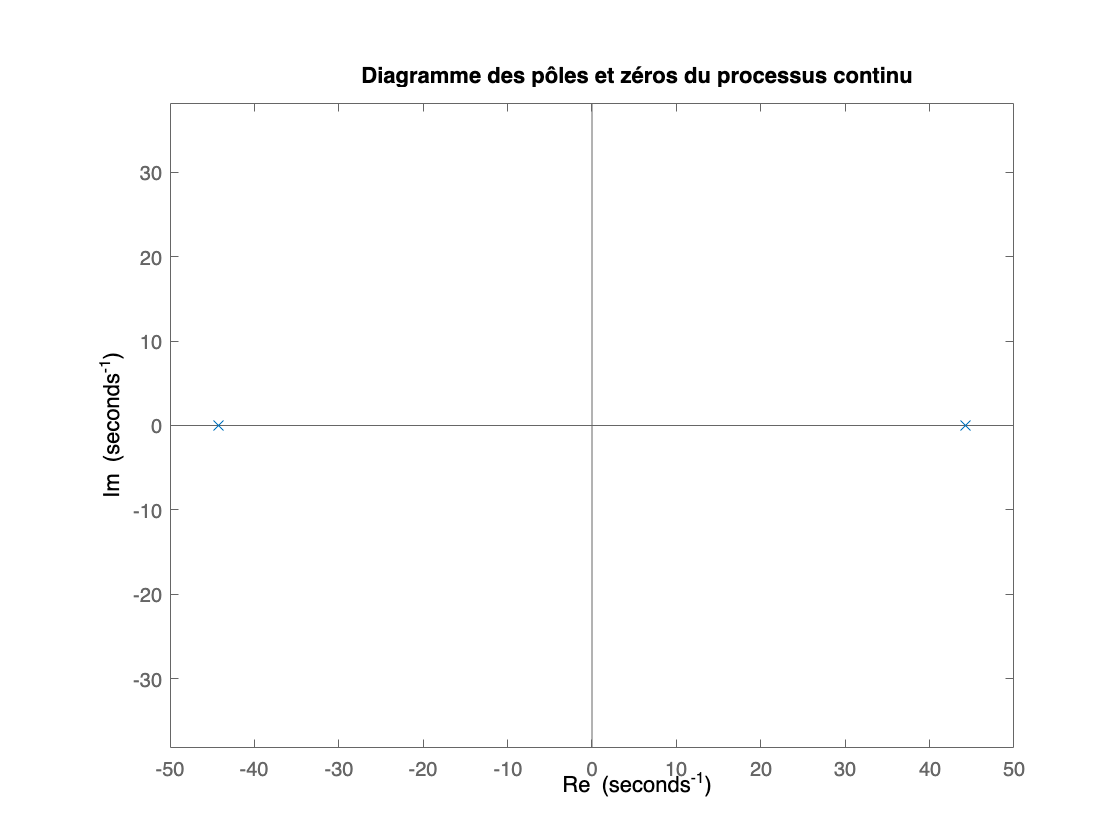

pzmap(H);
title('Diagramme des pôles et zéros du processus continu');
xlabel('Re');
ylabel('Im');
axis equal;

On obtient deux pôles 44.2945 et -44.2945, le système est donc clairement instable. Il n'y a pas de zéro pouvant perturber le fonctionnement du système en boucle ouverte.

**Analyse temporelle**

*Réponse indicielle*

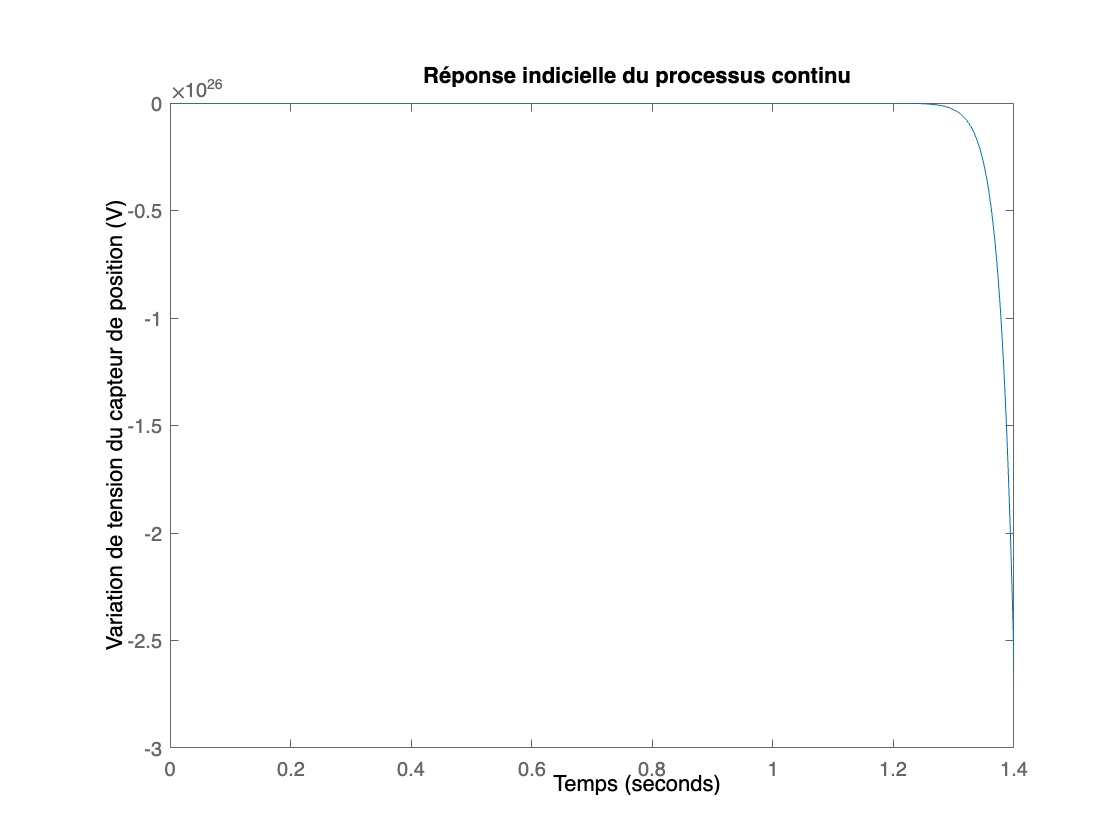

step(H);
title('Réponse indicielle du processus continu');
xlabel('Temps');
ylabel('Variation de tension du capteur de position (V)');

On remarque que la réponse indicielle diverge fortement (amplitude de 10^26 m atteinte en 1.2s). Le système est clairement instable, comme l'a montré l'analyse des pôles.

**Analyse fréquentielle**

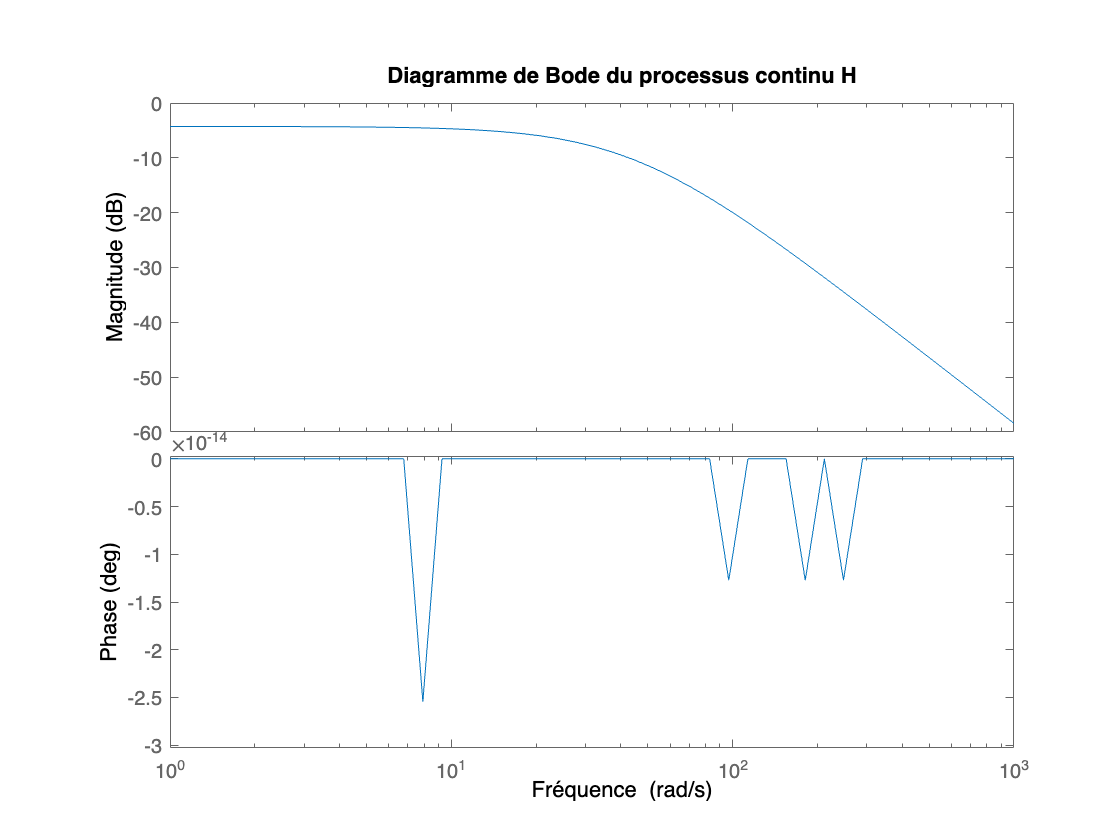

bode(H);
title('Diagramme de Bode du processus continu H');
xlabel('Fréquence');

On observe bien un comportement du second ordre avec un coefficient d'amortissement égal à 1. La pente est de -40dB/dec. La pulsation de coupure est de 44.3 rad/s. Comme la phase est quasi constante et égale à 0, la marge de gain est infinie, et la marge de phase l'est aussi car le gain n'est jamais égal à 0dB (le gain statique est de 0.6116 soit -2.1352dB).

**Discrétisation du modèle **

Période d'échantillonage

Te = 0.5*1e-3;

Discrétisation 

Hd = c2d(H,Te); 

Récupération du numérateur et dénominateur du processus discrétisé puis passage en $z^{-1}$

[B, A] = tfdata(Hd,'v');
Hd = filt(B,A,Te)

Hd =
 
  -0.00015 z^-1 - 0.00015 z^-2
  ----------------------------
       1 - 2 z^-1 + z^-2
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


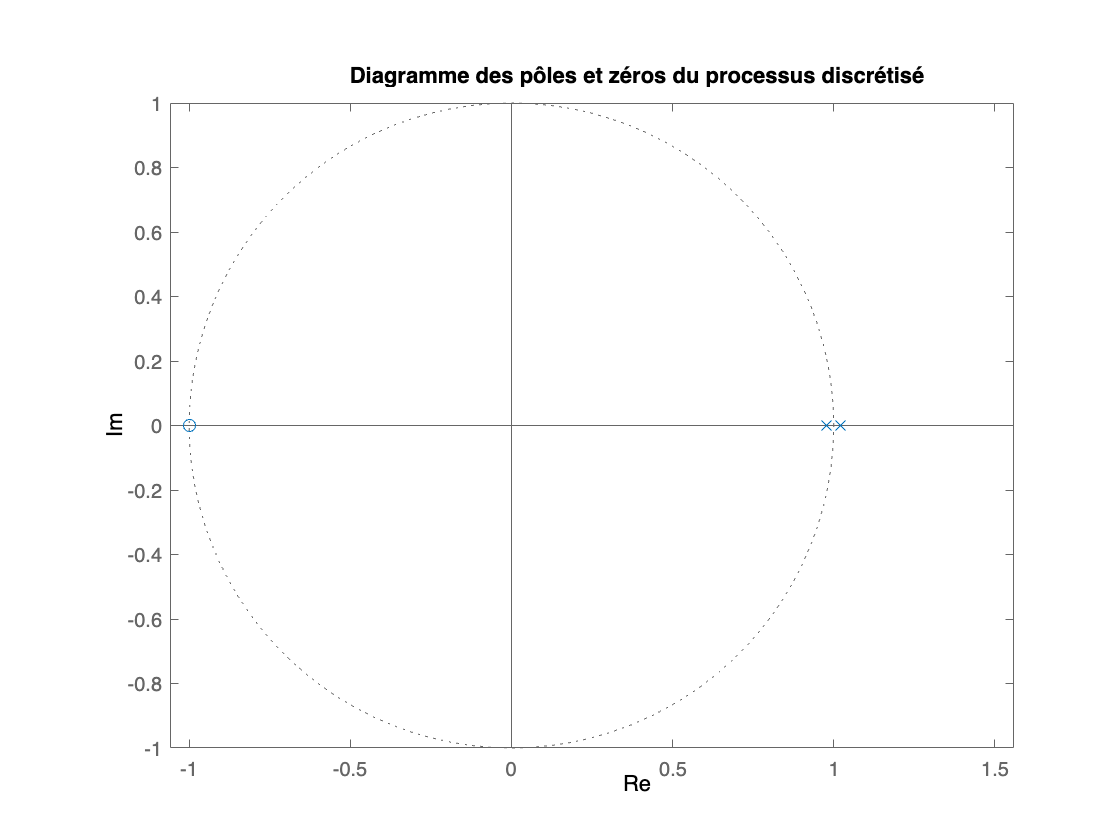

b1 = B(2);
b2 = B(3);

a1 = A(2);
a2 = A(3);

pzmap(Hd);
title('Diagramme des pôles et zéros du processus discrétisé');
xlabel('Re');
ylabel('Im');
axis equal;

poles = pole(Hd)

poles =     1.0224
    0.9781


zeros = zero(Hd)

zeros = -1.0000

La discrétisation du processus nous donne un modèle toujours instable, avec la présence d'un zéro en -1. Cette fois, le pôle instable est beaucoup plus proche de la zone de stabilité, représentée par le cercle unité. Les deux pôles sont en 1.0224 et 0.9781. Ainsi, il faudra faire attention à bien prendre en compte ce pôle instable lors de la synthèse des correcteurs.

**Pourquoi ne cherche-t-on pas à synthétiser un correcteur classique de type PID ou placement des pôles et des zéros ?  **

Les correcteurs de type PID ou par placement des pôles et des zéros ne permettent pas de garantir un comportement en asservissement sans dépassement, et donc ne garantissent pas le respect du cahier des charges.

**Cahier des charges en régulation**

tau_y = 21.4 * 1e-3; %Constante de temps du cahier des charges en régulation
Gamma_r = tf(1, [tau_y 1]);

GammaZ_r = c2d (Gamma_r, Te); %Discrétisation du cahier des charges de la régulation en sortie
GammaZ_r = filt(GammaZ_r.Numerator,GammaZ_r.Denominator,Te) %Passage en z^-1

GammaZ_r =
 
   0.02309 z^-1
  ---------------
  1 - 0.9769 z^-1
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


**Cahier des charges en asservissement**

On ne veut pas de dépassement, un Tr5% = Tr, dZ = +-5 mm, et pas d'erreur statique en sortie. Il faut se référer aux abaques pour trouver la valeur du coefficient d'amortissement puis celle de la pulsation propre.

Tr = 107*1e-3; %Temps de réponse à 5%
Xhi = 1; %Pas de dépassement
w0 = 4.74/Tr; %cf. abaque

Gamma_a = tf(1,[1/w0^2 2*Xhi/w0 1]);
GammaZ_a = c2d(Gamma_a,Te); %Discrétisation du cahier des charges en asservissement
GammaZ_a = filt(GammaZ_a.Numerator,GammaZ_a.Denominator,Te) %Passage en z^-1

GammaZ_a =
 
  0.0002417 z^-1 + 0.0002382 z^-2
  -------------------------------
   1 - 1.956 z^-1 + 0.9567 z^-2
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


## **Synthèse d'une commande par correcteur RST**

**Calcul de la fonction G**

Gamma_approx = filt([0 1],1,Te); %Gamma_approx = z^-1
G = GammaZ_a/Gamma_approx;

**Précaractérisation**

Rp = 1;
Sp = [1 -1]; %on travaille avec les coefficients : Sp = 1 - z^-1

**Calcul du degré des différents polynômes**

degP = 3 + 2 + 0 - 1; %4
degD = 2 + 0 - 1; %1
degF = 3 - 1; %2

**Caractérisation du polynôme P = Pz * Pa * Pp**

[numGammaZ_r, Pp] = tfdata(GammaZ_r,'v'); %Pp est le dénominateur du cahier des charges en régulation
Pa = 1;

%Le processus discrétisé a un pôle instable et un pôle stable
As = filt([poles(1) -1],1,Te);
Ai = filt([poles(2) -1],1,Te);

Pz = tfdata(As,'v'); %Correspond au pôle stable du processus discrétisé

P = conv(Pa,conv(Pz,Pp)); %Cela donne un polynôme de degré 2
P = [P 0 0]'; %P de degré 4 avec p3 = p4 = 0


**Résolution de l'équation de Bézout** : $P=C\ldotp D+E\ldotp F$

D'après le calcul des degrés, on a :

$D\left(z\right)=d_0 +d_1 \ldotp z^{-1}$, $F\left(z\right)=f_0 +f_1 \ldotp z^{-1} +f_2 \ldotp z^{-2}$, $P\left(z\right)=p_0 +p_1 \ldotp z^{-1} +p_2 \ldotp z^{-2} +p_3 \ldotp z^{-3} +p_4 \ldotp z^{-4}$avec $p_3 =p_4 =0$

Les inconnues sont les coefficients de D et de F. On connaît les polynômes C et E.

$C=A\ldotp S_p$et $E=R_p \ldotp B_i$

La solution de cette équation est la suivante : $P=\textrm{MX}$.

En développant l'équation de Bézout, et en identifiant les coefficients terme à terme, on obtient l'équation suivante : 

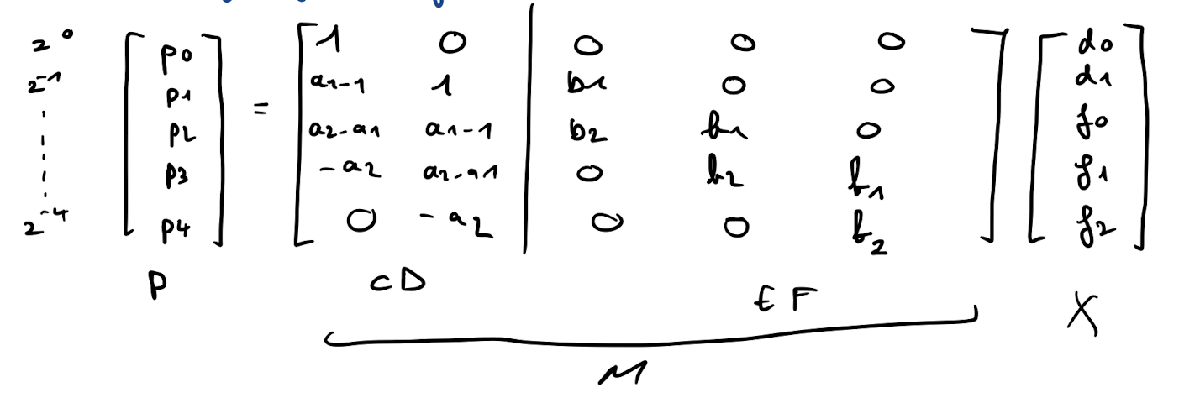

M = [1 0 0 0 0 ; a1-1 1 b1 0 0; a2-a1 a1-1 b2 b1 0; -a2 a2-a1 0 b2 b1; 0 -a2 0 0 b2];

X = inv(M)*P;

D = X(1:2)';
F = X(3:5)';

Enfin, on peut calculer les 3 polynômes R, S et T


$$R=F\ldotp R_p$$



$$S=D\ldotp S_p \ldotp B_s$$



$$T=\frac{P}{B_i \left(1\right)}=\frac{P}{b_1 +b_2 }$$


%Présence d'un zéro instable sur le cercle unité.
Bs_rst = 1;
Bi_rst = filt(B,1,Te);
%Enfin
R = conv(F,Rp);
S = conv(D,conv(Sp,Bs_rst));
T = (P/(b1+b2))';

Rz = filt(R,1,Te);
Sz = filt(S,1,Te);
Tz = filt(T,1,Te);

**Robustesse du correcteur RST**

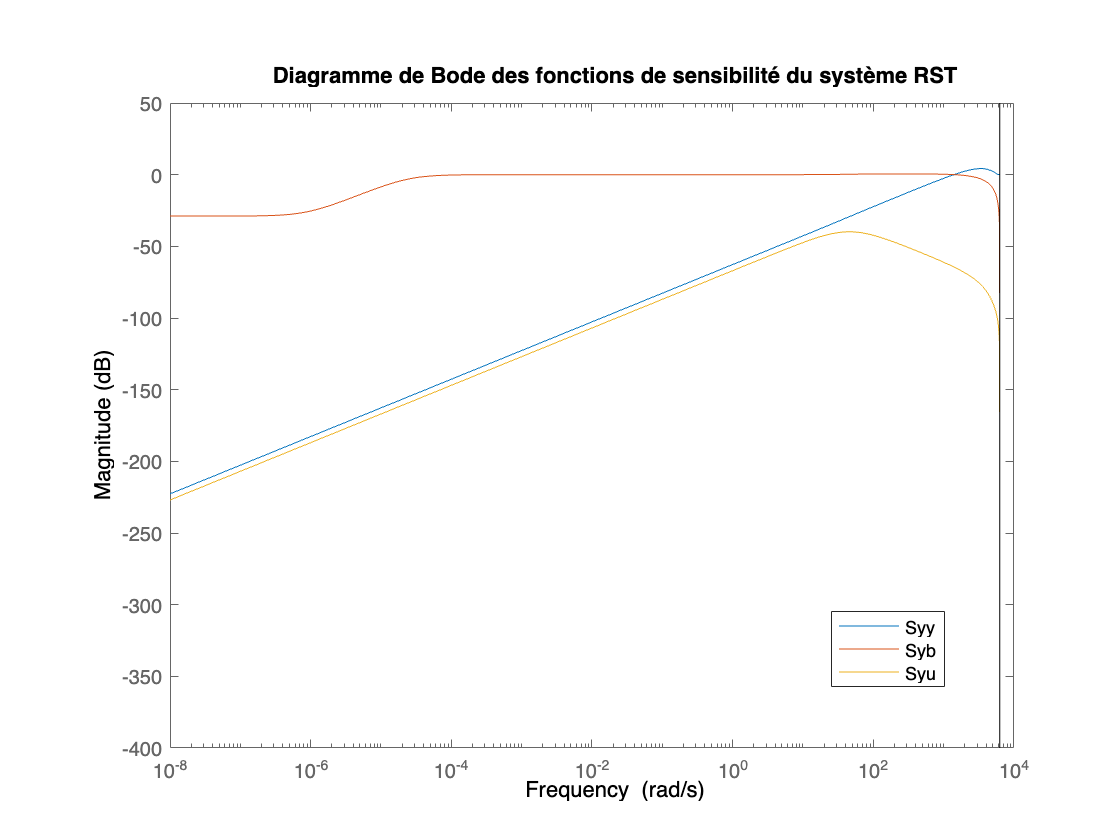

FTBO_rst = Rz/Sz*Hd; %fonction de transfert en BO
Syy_rst = 1/(1+FTBO_rst); %fonction de sensibilité sur la sortie
Syb_rst = -FTBO_rst/(1+FTBO_rst);
Syu_rst = Hd/(1+FTBO_rst);
bodemag(Syy_rst,Syb_rst,Syu_rst);
legend('Syy','Syb','Syu');
legend("Position", [0.74155,0.18181,0.10179,0.090476])
title('Diagramme de Bode des fonctions de sensibilité du système RST');

**Marges** 

marge_module_rst = -max(bode(Syy_rst))

marge_module_rst = -1.6252

allmargin(FTBO_rst)

ans = struct with fields:
     GainMargin: [0.0325 2.8708 7.3761e+15]
    GMFrequency: [44.6524 4.1893e+03 6.2832e+03]
    PhaseMargin: 59.7243
    PMFrequency: 1.4022e+03
    DelayMargin: 1.4868
    DMFrequency: 1.4022e+03
         Stable: 1


*à 44.65 rad/s : marge de gain*

m_gain1 = abs(20*log10(allmargin(FTBO_rst).GainMargin(1)))

m_gain1 = 29.7637

*à 4190 rad/s : marge de gain*

m_gain2 = abs(20*log10(allmargin(FTBO_rst).GainMargin(2)))

m_gain2 = 9.1602

*à 1402 rad/s : marges de phase et de retard*

m_phase1 = allmargin(FTBO_rst).PhaseMargin(1)

m_phase1 = 59.7243

allmargin(FTBO_rst).DelayMargin

ans = 1.4868

Grâce à cette étude, on peut déterminer aisément les différentes marges. La fonction allmargin nous donne une marge de phase de 59.72° (et de retard de 1.4868s) à 1402 rad/s, ainsi qu'une marge de gain de 9.16dB à 4190 rad/s. 

Mais notre système a un cahier des charges en asservissement avec une fréquence de coupure de 44.3 rad/s. A cette pulsation, la marge de gain est de 29.76dB. Ceci est très satisfaisant. On pourrait renforcer la robustesse du correcteur RST en ajoutant des pôles auxiliaires (en prenant par exemple Pa = (1 - alpha * z^-1) avec alpha = 0.4, mais ce n'est pas nécessaire ici.

Si on s'intéresse à la fonction de sensibilité sur la sortie Syy, on lit son maximum et on obtient la marge de module. Celle-ci est de -1.62dB. On veut qu'elle soit plus grande que 0.6 (ou -4.43dB), cette condition est vérifiée, le correcteur est suffisamment robuste.

**Méthode d'anti-saturation**

Il s'agit de mettre en oeuvre une méthode "anti-windup". On peut pour cela utiliser le bloc PID de Simulink et notamment son bloc intégrateur intégré. Celui-ci intègre une méthode d'anti-saturation basé sur la "back calculation". Je n'ai pas réussi à la mettre en oeuvre.

## **Synthèse d'une commande par modèle interne**

**Etude du prébouclage**

kp = -3.8883;
kd = -0.0789;

prebouclage = tf([kd kp],1); %Fonction de prébouclage continue
prebouclage_d = kp + kd*(1-filt([0 1],1,Te))/Te %Fonction de prébouclage discrétisée

prebouclage_d =
 
  -0.08084 + 0.0789 z^-1
  ----------------------
          0.0005
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


**Processus prébouclé**

Hcmi = H/(1+H*prebouclage); 
Hcmi_d = minreal(c2d(Hcmi,Te));
Hcmi_d = filt(Hcmi_d.Numerator,Hcmi_d.Denominator, Te); %Passage en z^-1

[B_cmi, A_cmi] = tfdata(Hcmi_d,'v');

**Etude de la stabilité du processus prébouclé**

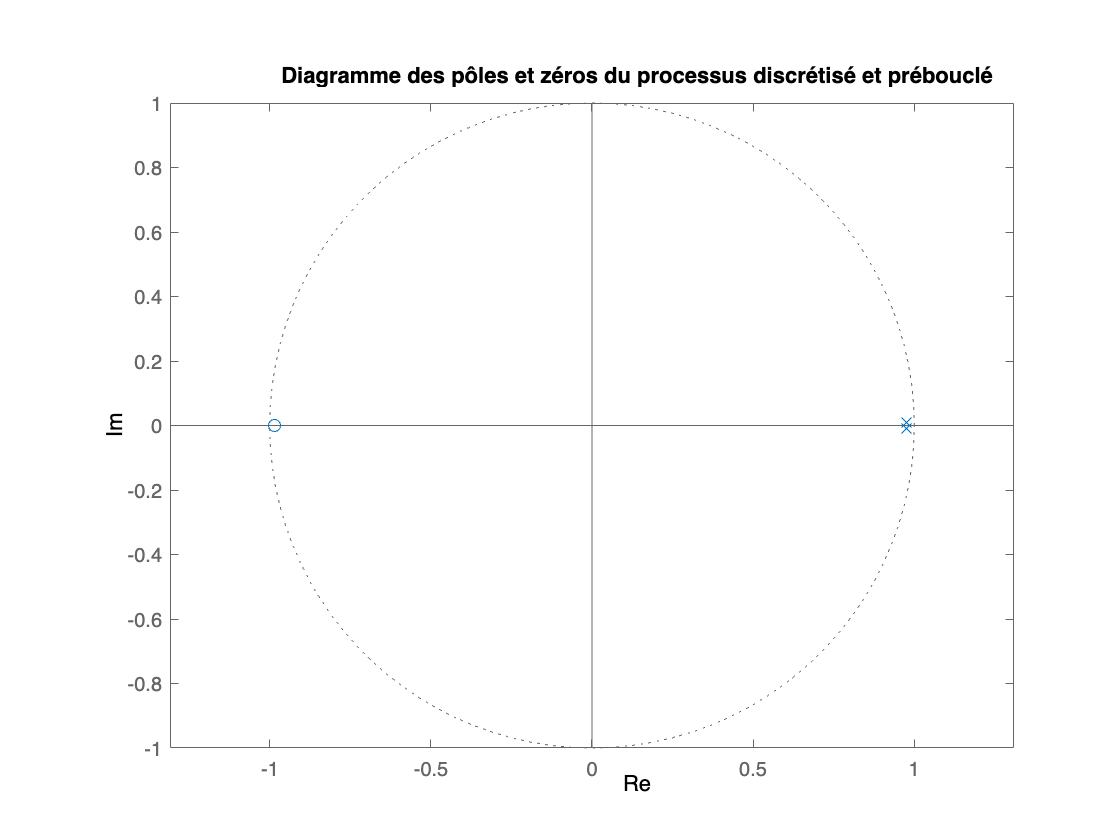

pzmap(Hcmi_d);
title('Diagramme des pôles et zéros du processus discrétisé et prébouclé');
xlabel('Re');
ylabel('Im');
axis equal;

pole(Hcmi_d)

ans =    0.9766 + 0.0105i
   0.9766 - 0.0105i


zero(Hcmi_d)

ans = -0.9843

La fonction de transfert Hcmi possède un zéro dans le cercle unité qui impacte la dynamique du système en boucle ouverte, ainsi que deux pôles conjugués situés dans le cercle unité. Le processus prébouclé est donc stable, et on se rend bien compte de l'intérêt du prébouclage pour rendre le processus stable. Sans cela, il serait impossible de synthétiser le correcteur par modèle interne.

**Calcul du correcteur avec le prébouclage**

b1_cmi = B_cmi(2);
b2_cmi = B_cmi(3);

Bi_cmi = filt(B_cmi,1,Te); %Bi(z) = b1 z^-1 + b2 z^-2. B(2) correspond bien à b1
Gamma_cmi = Bi_cmi/(b1_cmi+b2_cmi); %Calcul de Gamma nécessaire pour calculer les autres blocs

**Calcul de la fonction C **

Cette fonction permet d'inverser le modèle.

C = minreal(Gamma_cmi/Hcmi_d)

C =
 
  -3413 + 6666 z^-1 - 3255 z^-2
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


**Calcul de la fonction G **

Cette fonction correspond à la dynamique en asservissement

G = GammaZ_a/Gamma_approx

G =
 
   0.0002417 + 0.0002382 z^-1
  ----------------------------
  1 - 1.956 z^-1 + 0.9567 z^-2
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


**Calcul de la fonction  F**

Cette fonction correspond à la dynamique en régulation.

F = GammaZ_r/Gamma_approx %Correspond à la dynamique en régulation

F =
 
      0.02309
  ---------------
  1 - 0.9769 z^-1
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


**Robustesse de la CMI**

*Sans le prébouclage*

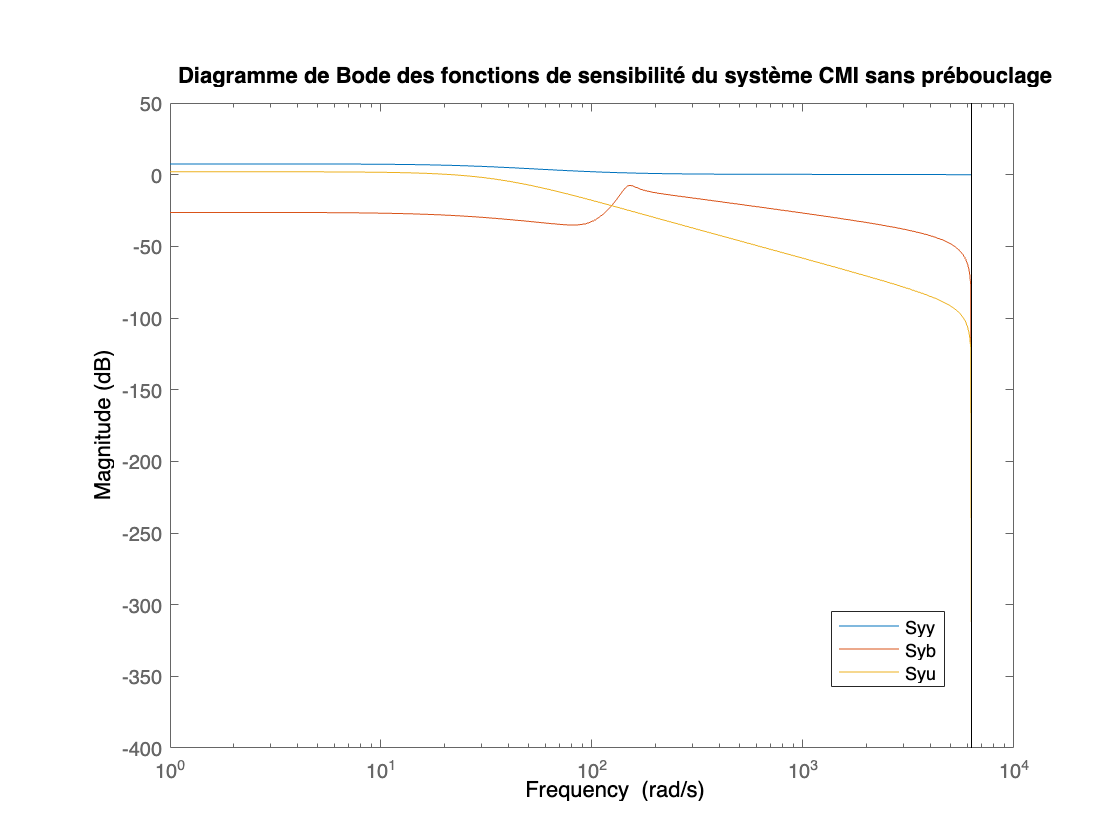

K2_sp = C*F/(1-C*F*Hd); %K2 = R/S, H = B/A, Syy = AS/(AS+BR)
FTBO_cmi_sp = K2_sp * Hd;

Syy_cmi_sp = 1/(1+FTBO_cmi_sp);
Syb_cmi_sp = FTBO_cmi_sp/(1+FTBO_cmi_sp);
Syu_cmi_sp = Hd/(1+FTBO_cmi_sp);

bodemag(Syy_cmi_sp,Syb_cmi_sp,Syu_cmi_sp);
legend('Syy','Syb','Syu');
legend("Position", [0.74155,0.18181,0.10179,0.090476])
title('Diagramme de Bode des fonctions de sensibilité du système CMI sans prébouclage');

marge_module_cmi_sp = -max(bode(Syy_cmi_sp))

marge_module_cmi_sp = -2.3775

allmargin(FTBO_cmi_sp)

ans = struct with fields:
     GainMargin: [1.7256 85.5796 3.7166e+17]
    GMFrequency: [0 3.1173e+03 6.2832e+03]
    PhaseMargin: [1×0 double]
    PMFrequency: [1×0 double]
    DelayMargin: [1×0 double]
    DMFrequency: [1×0 double]
         Stable: 0


m_gain1 = abs(20*log10(allmargin(FTBO_cmi_sp).GainMargin(1)))

m_gain1 = 4.7390

m_gain2 = abs(20*log10(allmargin(FTBO_cmi_sp).GainMargin(2)))

m_gain2 = 38.6474

m_gain3 = abs(20*log10(allmargin(FTBO_cmi_sp).GainMargin(3)))

m_gain3 = 351.4028

On peut déterminer les différentes marges. La fonction allmargin nous donne une marge de phase infinie ainsi qu'une marge de gain de 4.74 dB à 0 rad/s, 38.65 dB à 3180 rad/s et 351.40 dB à 3717 rad/s.

Si on s'intéresse à la fonction de sensibilité sur la sortie Syy, on lit son maximum et on obtient la marge de module. Celle-ci est de -2.38 dB, ce qui assez satisfaisant car cette valeur est plus grande que -4.43dB. Cela reste assez faible. L'intérêt du prébouclage est de rendre le processus stable et d'améliorer la robustesse du correcteur.

*Avec le prébouclage *

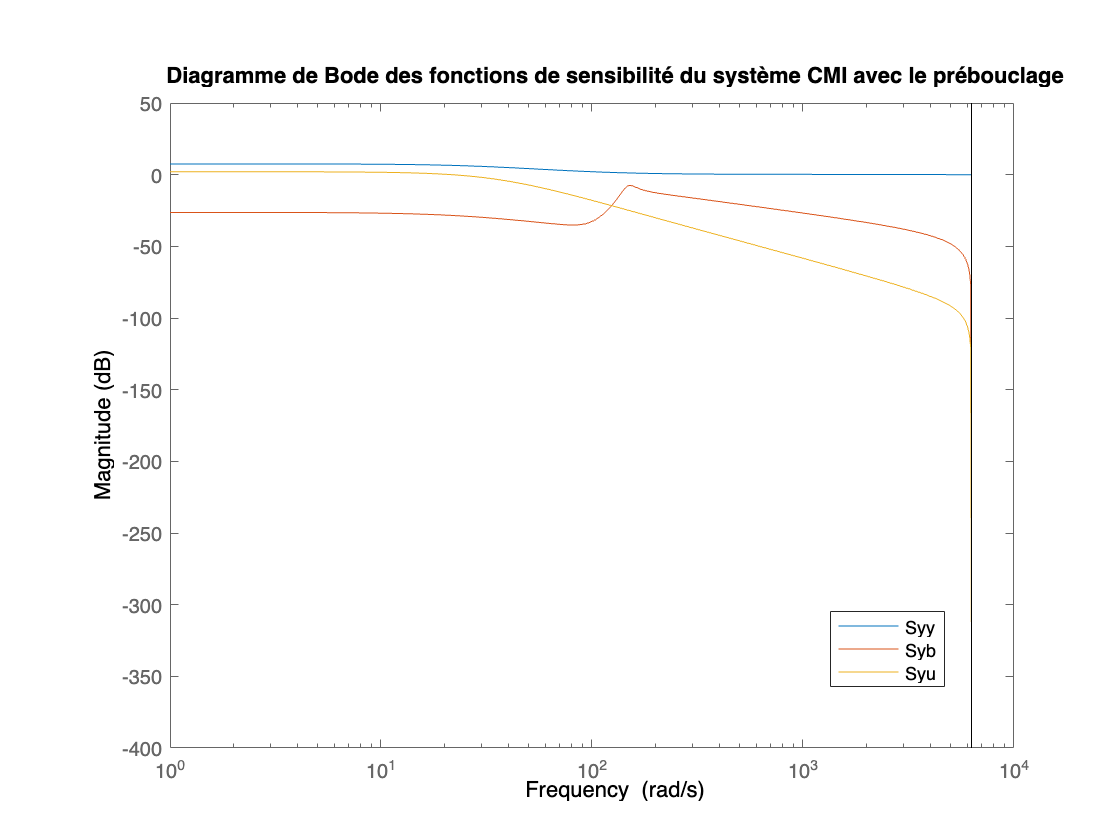

K2_ap = C*F/(1-C*F*Hcmi_d); %K2 = R/S, H = B/A, Syy = AS/(AS+BR)
FTBO_cmi_ap = K2_ap * Hcmi_d;
Syy_cmi_ap = 1/(1+FTBO_cmi_ap);
Syb_cmi_ap = FTBO_cmi_ap/(1+FTBO_cmi_ap);
Syu_cmi_ap = Hd/(1+FTBO_cmi_ap);
bodemag(Syy_cmi_sp,Syb_cmi_sp,Syu_cmi_sp);
legend('Syy','Syb','Syu');
legend("Position", [0.74155,0.18181,0.10179,0.090476])
title('Diagramme de Bode des fonctions de sensibilité du système CMI avec le prébouclage');

marge_module_cmi_sp = -max(bode(Syy_cmi_ap))

marge_module_cmi_sp = -1.0208

allmargin(FTBO_cmi_ap)

ans = struct with fields:
     GainMargin: [6.7124e-06 88.2926 1.0851e+04]
    GMFrequency: [0 3.1806e+03 6.2832e+03]
    PhaseMargin: 88.7119
    PMFrequency: 45.6624
    DelayMargin: 67.8158
    DMFrequency: 45.6624
         Stable: 1


m_gain1 = abs(20*log10(allmargin(FTBO_cmi_ap).GainMargin(1)))

m_gain1 = 103.4624

m_gain2 = abs(20*log10(allmargin(FTBO_cmi_ap).GainMargin(2)))

m_gain2 = 38.9185

m_gain3 = abs(20*log10(allmargin(FTBO_cmi_ap).GainMargin(3)))

m_gain3 = 80.7095

On peut déterminer les différentes marges. La fonction allmargin nous donne une marge de phase de 88.71° à 45.66 rad/s ainsi qu'une marge de gain de 103.46 dB à 0 rad/s, 38.91 dB à 3180 rad/s et 80.7 dB à 6283 rad/s.

Si on s'intéresse à la fonction de sensibilité sur la sortie Syy, on lit son maximum et on obtient la marge de module. Celle-ci est de -1.02 dB, ce qui assez satisfaisant car cette valeur est plus grande que -4.43dB, et plus grande que sans le prébouclage. On se rend compte que le prébouclage permet donc bien d'augmenter la robustesse de notre correcteur.

**Algorithme sur microcontrôleur : **

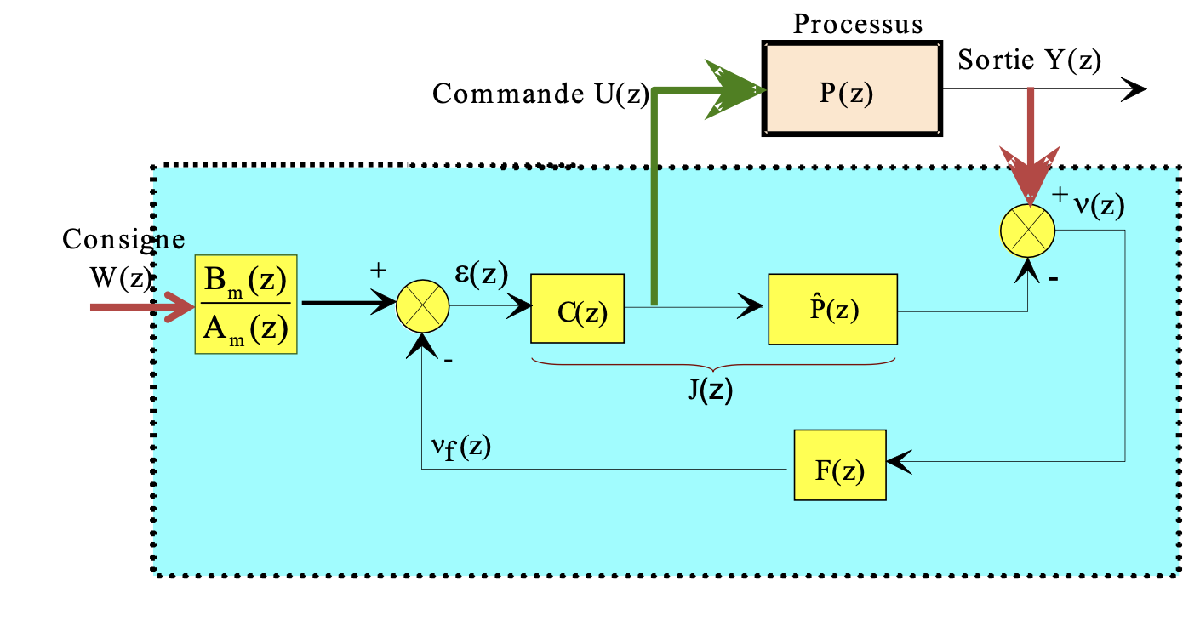

On commence par initialiser les deux premières valeurs des différents signaux.

$\begin{array}{l}
\textrm{for}\;\left(\int \;i=0;i\le 1;i++\right):\\
y\left(i\right)=0;\\
\hat{y} \left(i\right)=0;\\
\textrm{dy}\left(i\right)=0;\\
{\textrm{dy}}_{\textrm{filtre}} \left(i\right)=0;\\
w\left(i\right)=0;\\
w_{\textrm{inter}} \left(i\right)=0;\\
u\left(i\right)=0;\\
\epsilon \left(i\right)=0;
\end{array}$;

**Puis**


$$\begin{array}{l}
k=2\\
\textrm{while}\;\left(1\right):
\end{array}$$


- Acquisition de la consigne de position z de la rame **W**, et de la tension mesurée du capteur de position **Y***.*


$$\begin{array}{l}
w\left(k\right)=W;\\
y\left(k\right)=Y;
\end{array}$$


2. Calcul de la sortie du modèle du processus $\hat{y}$

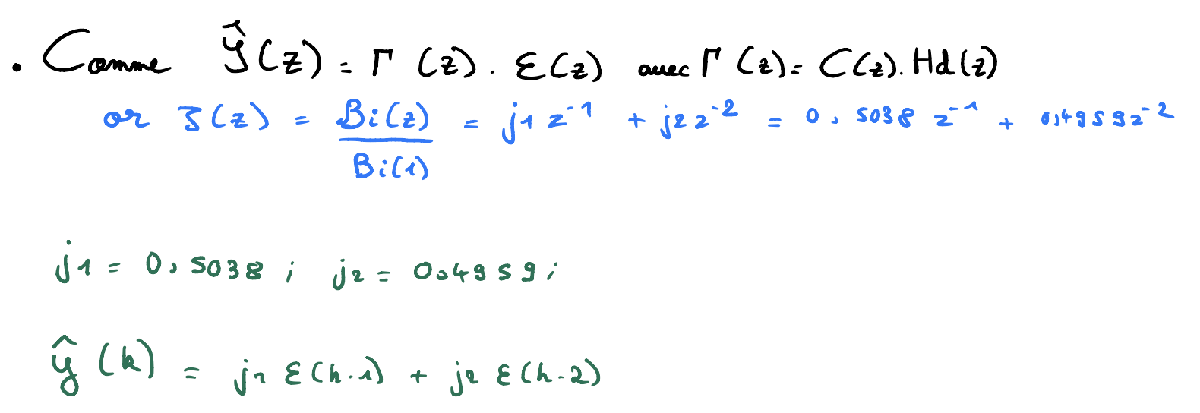

3. Calcul de la consigne intermédiaire $w_{\textrm{inter}}$

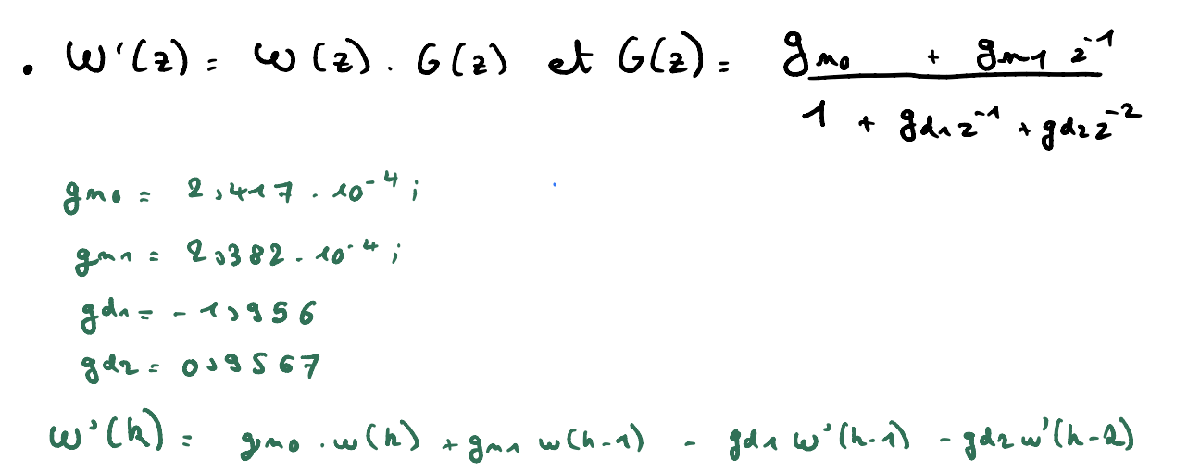

4. Calcul du signal d'écart en sortie $\textrm{dy}$

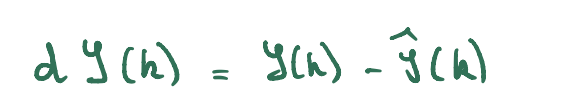

5. Calcul du signal d'écart filtré ${\textrm{dy}}_{\textrm{filtre}}$

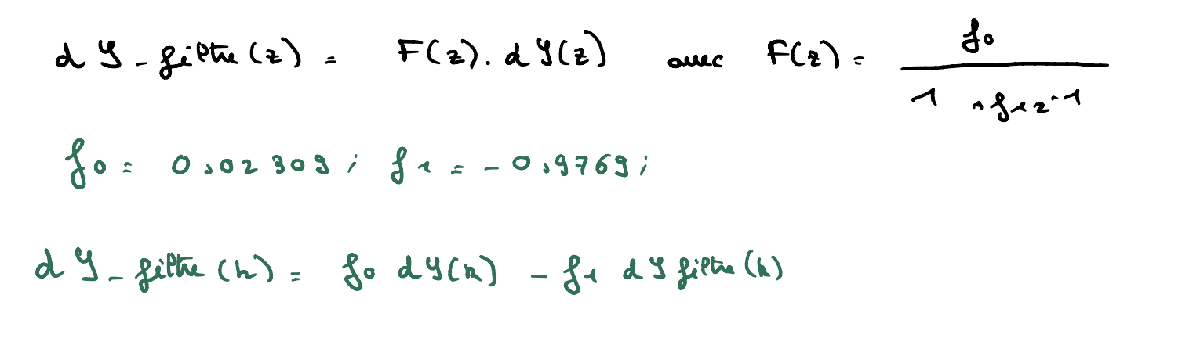

6. Calcul du signal d'écart en entrée $\epsilon$


$$\epsilon \left(k\right)=w_{\textrm{inter}} \left(k\right)-{\textrm{dy}}_{\textrm{filtre}} \left(k\right)$$


7. Calcul de la commande $u$

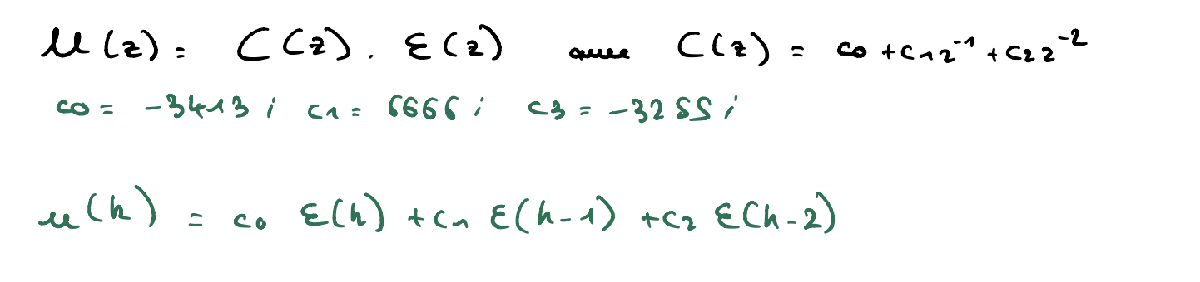

8. Incrémentation de k


$$k=k+1;$$


## Résultats des simulations sur Simulink

**RST**

Linéaire 

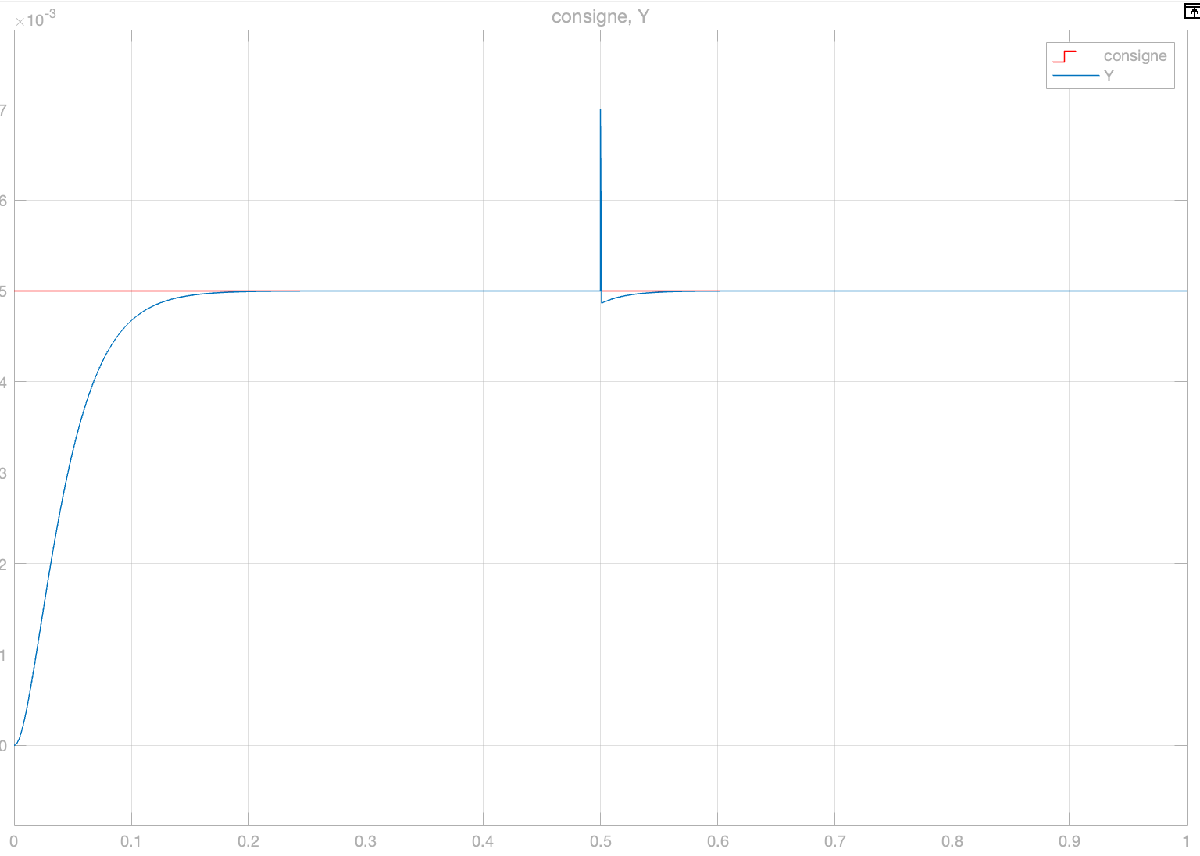

Détaillé

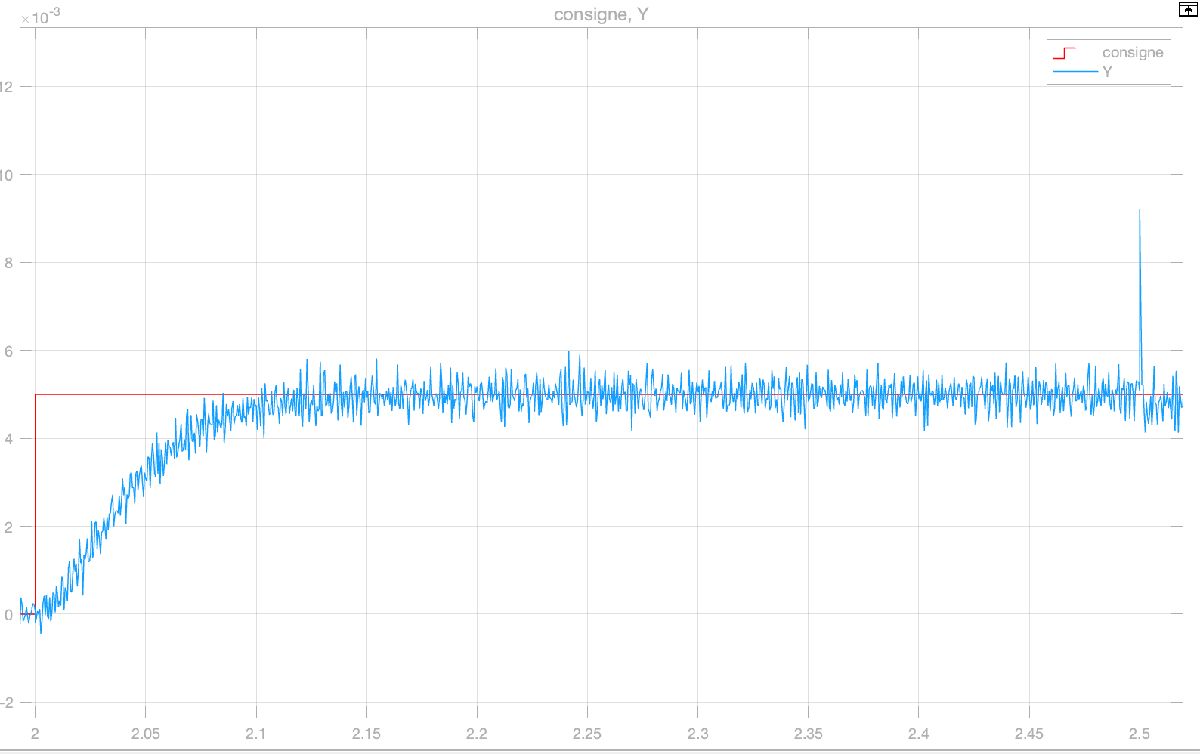

**CMI **

Linéaire

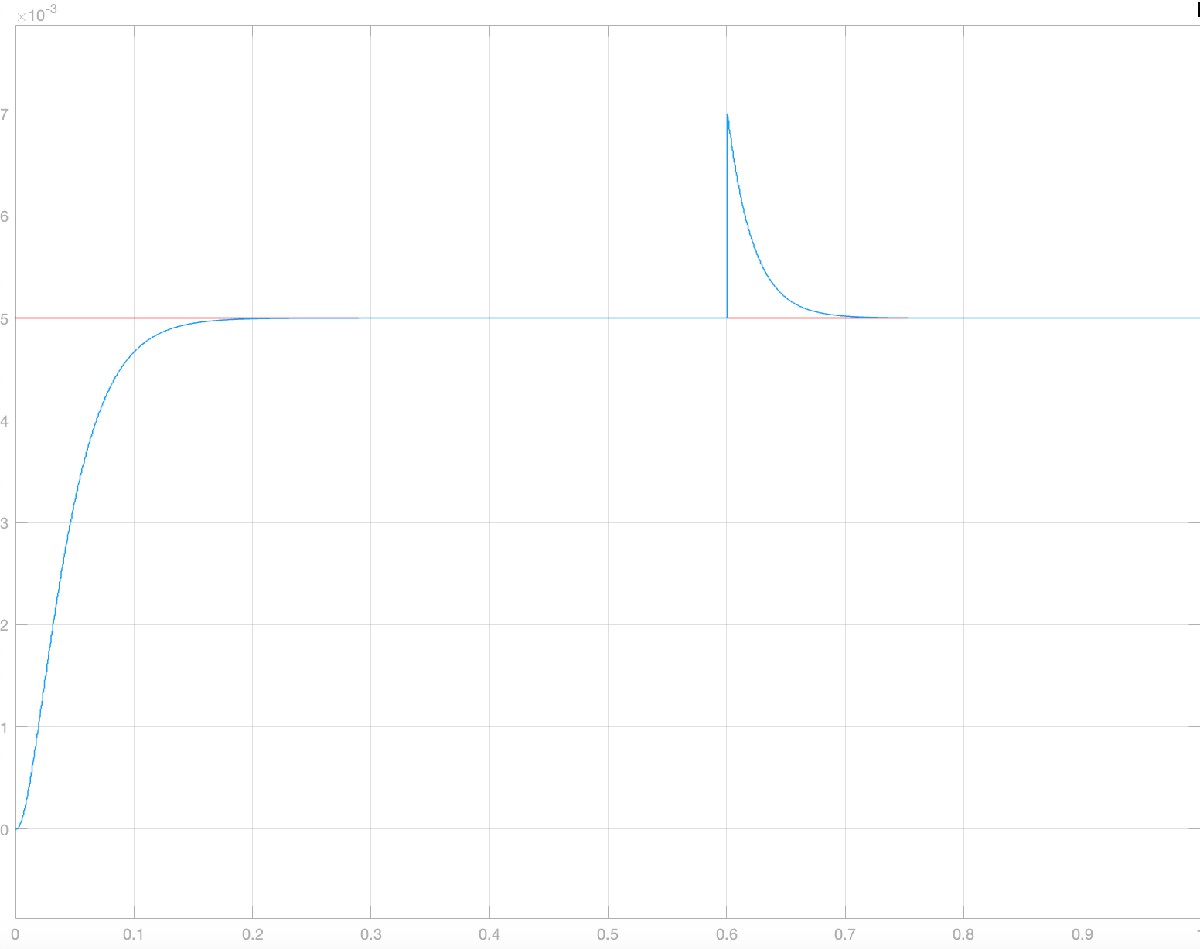

Détaillé 

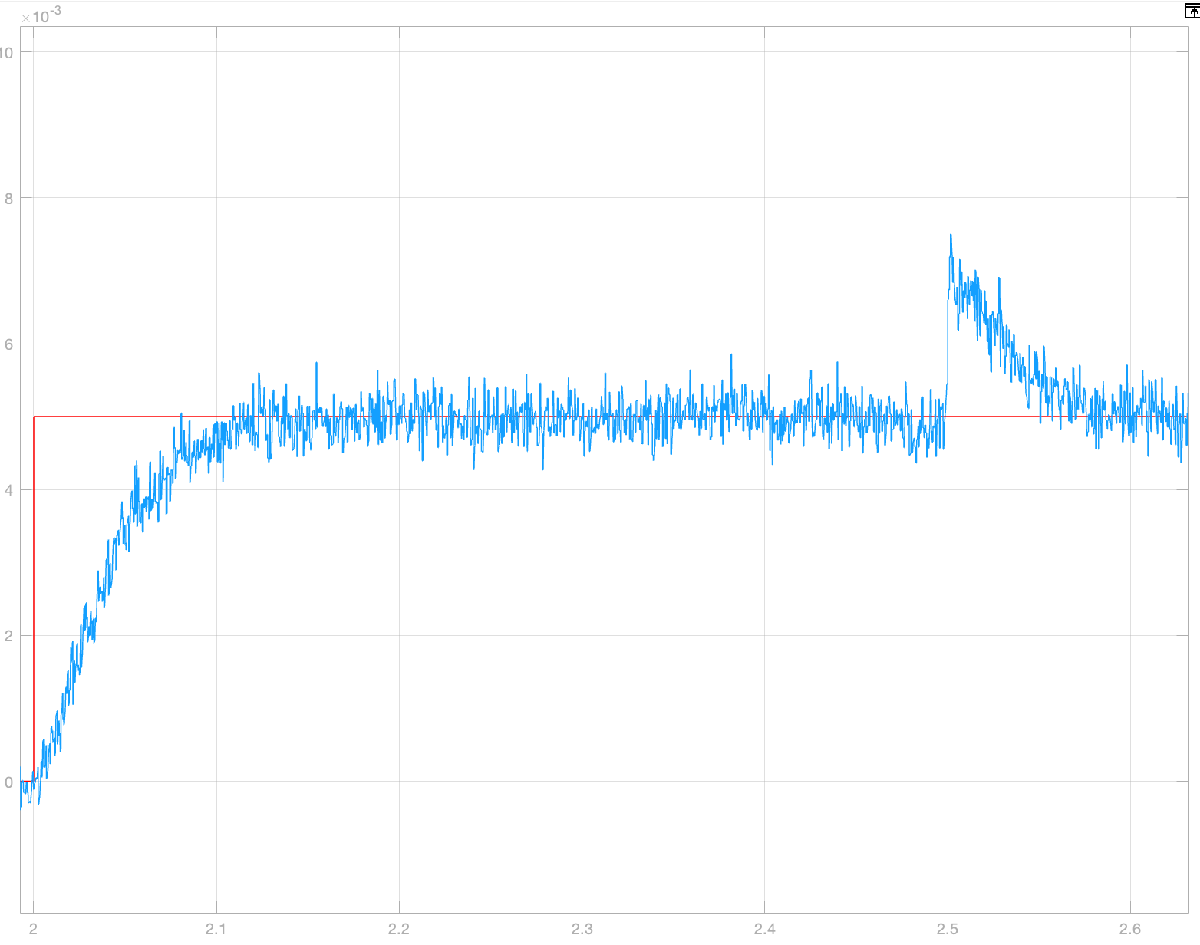

## Conclusion

Les deux correcteurs synthétisés respectent le cahier des charges. On n'observe pas de dépassement et le temps de réponse à 5% est correct. De plus, la perturbation en sortie est rejetée avec une dynamique du premier ordre et vérifie bien la constante de temps spécifiée dans le document Excel. Enfin, il n'y a aucune erreur statique et les deux correcteurs sont assez robustes. 

Je privilégie l'utilisation du correcteur RST car je trouve qu'il est plus facile à mettre en place car il ne nécessite pas de prébouclage. Le projet était intéressant à mener car il permet de développer ses connaissances dans la synthèse de différents types de correcteurs, mais il y a des difficultés que je n'ai pas réussi à surmonter comme la mise en oeuvre de la méthode d'antisaturation pour le correcteur RST.